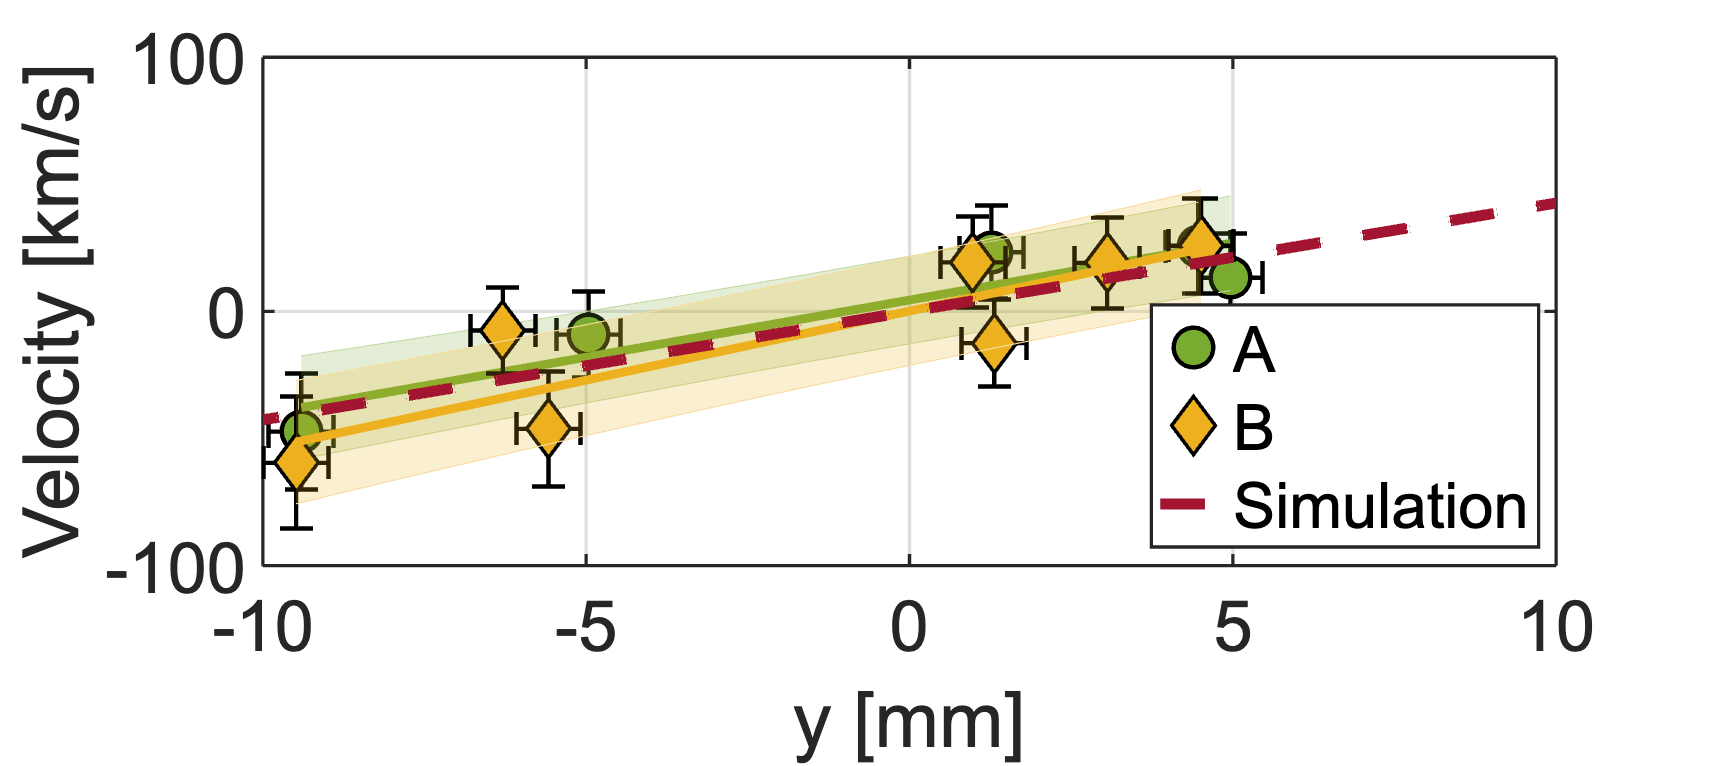

clc; close all; clear;

load UXI2_Velocity.mat


errorbar(y0_mm,velocity/1e3,dv/1e3,linewidth=2,color='k',linestyle='none',capsize=15,HandleVisibility='off'); hold on;
errorbar(y0_mm,velocity/1e3,ds*ones(size(y0_mm)),'horizontal',linewidth=2,color='k',linestyle='none',capsize=15,HandleVisibility='off')
plot(y0_mm,velocity/1e3,'o',markersize=18,linewidth=2,color='k',markerfacecolor='#77AC30',DisplayName='A'); hold on;
formatPlots(900,2.25);
grid(); legend('off');
ylim([-100,100]); xlim([-10,10])
xlabel('y [mm]'); ylabel('Velocity [km/s]')

% Fit 
ft = fit(y0_mm,velocity,'poly1');
xx = linspace(min(y0_mm),max(y0_mm),100);
plot(xx,ft(xx)/1e3,'k-','LineWidth',4,'DisplayName','off','Color','#77AC30','HandleVisibility','off');

CIO = predint(ft,xx',0.68,'obs');

shadedErrorBar(xx,ft(xx)/1e3,(CIO(:,1)'-ft(xx)')/1e3,'lineProps',{'Color','#77AC30','HandleVisibility','off'});

%  UXI 2

load UXI1_Velocity.mat

y0_mm = y0_mm + 1;
errorbar(y0_mm,velocity/1e3,dv/1e3,linewidth=2,color='k',linestyle='none',capsize=15,HandleVisibility='off'); hold on;
errorbar(y0_mm,velocity/1e3,ds*ones(size(y0_mm)),'horizontal',linewidth=2,color='k',linestyle='none',capsize=15,HandleVisibility='off')
plot(y0_mm,velocity/1e3,'D',markersize=18,linewidth=2,color='k',markerfacecolor='#EDB120',DisplayName='B'); hold on;

% Fit 
ft = fit(y0_mm,velocity,'poly1');
xx = linspace(min(y0_mm),max(y0_mm),100);
plot(xx,ft(xx)/1e3,'k-','LineWidth',4,'DisplayName','off','Color','#EDB120','HandleVisibility','off');

CIO = predint(ft,xx',0.68,'obs');

shadedErrorBar(xx,ft(xx)/1e3,(CIO(:,1)'-ft(xx)')/1e3,'lineProps',{'Color','#EDB120','HandleVisibility','off'});



% Simulaion

Yq = dlmread('sims/Yq.txt');
Tid = dlmread('sims/Tid.txt');
V = dlmread('sims/velocity.txt');

v = V(:,1) * 0;

for ii = 220:10:250
t = ii; % ns
idx = find(Tid == t);
v =  v + V(:,idx);
end

Vq = v / numel(220:10:250);


plot(Yq*1e3,Vq/1e3,'--',linewidth=5,color='#A2142F',DisplayName='Simulation');
legend('box','on','Location','southeast')
savePath = checkDir('/Users/rishabhdatta/Dropbox (MIT)/PUFFIN/Data/MARZ/Figures_POP/');
saveas(gcf,[savePath 'z3781_UXI_velocity.png']);